# Práctica 1

**Elaborado por:**

Federico Banoy Restrepo

Salomón Cardeño Luján

Juan David Rengifo Castro

## Datos

Es necesario cargar los datos suministrados por la empresa en este punto y se procede a realizar la descripción de cada variable del `workspace`.

clc; clear;
load('DataP1ModExp/data1.mat')

$u_{lineal}$: Función afín (500:10:1500).

$y_{sample}$: Respuesta a $u_{lineal}$ desde el punto estacionario de $571.9318$ -`unique(y_sample(:,1))`-.

$y_{response}$: Respuesta de la salida a una función escalon de 1000 a 1120.

$y$: Respuesta a la PRBS, pero restandole el primer valor a la serie.

$u$: PRBS entre -100 y y 120 (900 y 1120).

## Petición de la empresa

Cordial saludo ingenieros matemáticos. Nos comunicamos con ustedes porque necesitamos determinar un modelo para el comportamiento de cierta planta ultra secreta. Como podrán comprender, nos vemos en la obligación de reservarnos la mayor cantidad de información posible. Nosotros mismos ya hemos adelantado parte de los procesos necesarios para determinar el modelo. Sabemos que nuestra planta consta de una única entrada y una única salida, la entrada tiene un valor de 1000 unidades regularmente y la planta se mantiene en estado estacionario. Partiendo de este punto de estabilidad, nuestro anterior ingeniero varió el valor de la entrada en un rango de 500 a 1500 $(u_{lineal})$ tal y como pueden ver a continuación

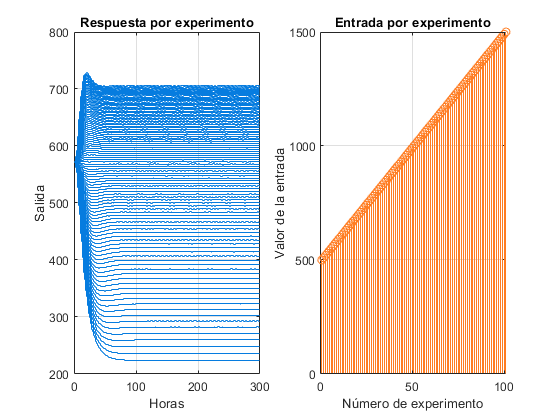

figure('Color', 'White')
subplot(1,2,1)
stairs(0:300,y_sample','Color', my_color('blue1'))
grid on
title('Respuesta por experimento')
xlabel('Horas'); ylabel('Salida')
subplot(1,2,2)
stem(u_lineal, 'Color', my_color('orange'))
grid on
title('Entrada por experimento')
xlabel('Número de experimento'); ylabel('Valor de la entrada')

Esta información se las compartimos a través de la matriz **y_sample** y el vector **u_lineal**. La primera fila de la matriz corresponde con el primer valor del vector como entrada. Para cada caso, se tomaron muestras del estado del sistema cada hora y esperamos hasta que el sistema se estabilizara. Luego, para un solo experimento, se aumentó lo máximo posible el esfuerzo de muestreo y se cambió la entrada del sistema de $1000$ a $1120$ de forma abrupta. Los datos de la respuesta del modelo se presentan a continuación:

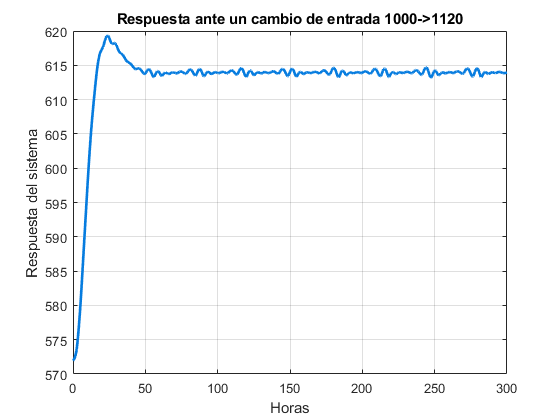

figure(2)
clf
% plot(t, y_sample(find(u_lineal==1120),:))
plot(t,y_response, 'LineWidth', 2, 'Color', my_color('blue1'))
grid on
xlabel('Horas')
ylabel('Respuesta del sistema')
title('Respuesta ante un cambio de entrada 1000->1120')

Con base en dicha información, nuestro anterior ingeniero decidió excitar el sistema con un periodo de muestreo de 1 hora y una señal PRBS (con un periodo igual al de muestreo) que variaba entre valores de 900 y 1120 para luego proceder a identificar un modelo apropiado para la planta, sin embargo, tuvimos que prescindir del ingeniero en este punto y el sistema no ha podido identificarse. Los datos recopilados se muestran a continuación

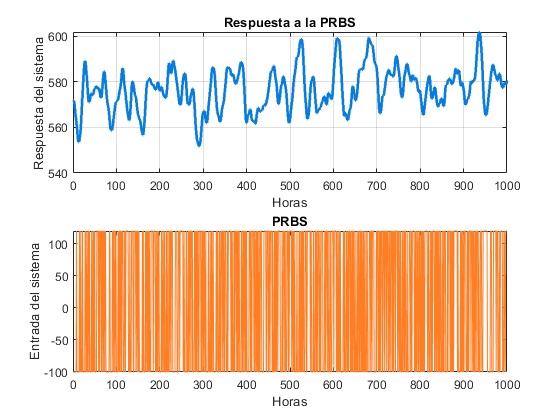

figure(3)
clf
subplot(2,1,1)
stairs(0:1000, y', 'LineWidth', 2, 'Color', my_color('blue1'))
grid on
title('Respuesta a la PRBS')
xlabel('Horas'); ylabel('Respuesta del sistema')
subplot(2,1,2)
plot(0:1000, u, 'Color', my_color('orange'))
xlabel('Horas'); ylabel('Entrada del sistema')
title('PRBS')

Nos hemos contactado con ustedes con la esperanza de que puedan evaluar la metodología que siguió nuestro anterior ingeniero (si es adecuada o si modificarían algo) y, en caso de que lo consideren posible, concluir el proceso de identificación del sistema. Les solicitamos el mayor detalle posible en sus respuestas así como en la justificación de porqué deberíamos confiar o no en el modelo que ustedes puedan identificar. Estaremos muy atentos. 

## Respuesta a la empresa

### Preeliminares

- Curva de linealización

- Respuesta a un escalon, estimación de segundo orden de los parámetros.

- Orden 2m mínimo.

- Teorema de continuidad de los parámetros

### Análisis trabajo previo

**Procedimiento 1: **El ingeniero anterior comenzó observando en que rango de la entrada el sistema se comporta de manera lineal. Para esto varió la entrada de $500$ a $1500%$ con tamaño de paso fijo de $10$. 

**Comentario:** Esto tiene sentido desde la matemática puesto que se escogió un intervalo centrado en la entrada usual y seleccionó un tamaño de paso fijo (una práctica común). No obstante, desconocemos si esta elección es consistente con el funcionamiento interno de la empresa, por lo que conviene contestar las siguientes preguntas: ¿este es un rango factible? ¿Una variación de 10 en la entrada es pequeña, sin serlo en exceso? Si las respuestas son afirmativas, consideramos que fue una elección adecuada.

**Procedimiento 2:** Para un solo experimento aumentó lo máximo posible el esfuerzo de muestreo y se cambió la entrada del sistema de $1000$ a $1120$ de forma abrupta.

**Comentario:** La elección de los parámetros de la función escalón empleada para la entrada debe corresponder a una región de funcionamiento lineal de la **curva de linealización**. Claramente, dicha región debe ser consistente con los valores de entrada que la empresa suele manejar. No tenemos resultados sobre estos procedimientos así que procedemos a realizarlo. Sin embargo, es evidente que la curva de linealización será no lineal concava hacia abajo, puesto que el punto de estabilización aumenta cada vez menos ante cambios constantes en la entrada. Es decir, estamos ante la presencia de un proceso con producción marginal decreciente.

**Resultados: **Comenzamos graficando la curva de linealidad y el intervalo escogido. Claramente, este rango es una buena aproximación lineal, no obstante, es cuestionable su elección, pues se podría obtener un rango más amplio o desplazado. Esto dependerá de las necesidades de la empresa, es decir, la región de variación de la entrada y la precisión deseada.

Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    _________    ______    __________

    (Intercept)     225.51         3.176    71.005    5.3714e-16
    x1             0.34727     0.0029944    115.97    2.4507e-18


Number of observations: 13, Error degrees of freedom: 11
Root Mean Squared Error: 0.404
R-squared: 0.999,  Adjusted R-Squared: 0.999
F-statistic vs. constant model: 1.34e+04, p-value = 2.45e-18


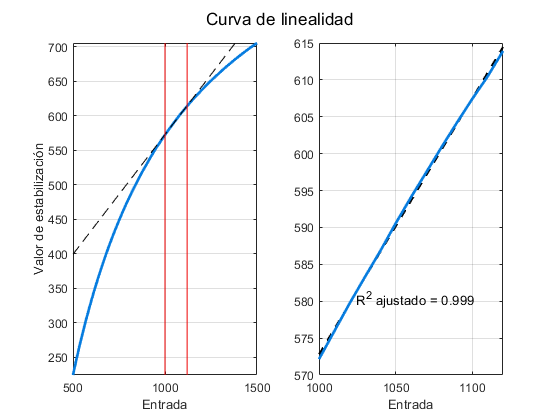

u_min = 1000;
u_max = 1120;

if (u_min < u_max)
    est = y_sample(:, end)'; % Estimación puntos de estabilidad.
    linear_curve(est, u_lineal, u_min, u_max)
else
    disp('Invalid input limits')
end

**Conclusión:** La elección no es erronea pero no necesariamente es óptima, es posible aumentar el rango de la entrada o desplazarlo y obtener significancia en el modelo de regresión lineal y un excelente ajuste. Esto dependerá de las necesidades de la empresa. Considerando que desconocemos dicha información asumimos que la empresa concuerda con los efectos prácticos de la elección del ingeniero anterior.

**Procedimiento 3:** Elección de un periodo de muestreo de excitación de 1 hora.

**Comentario: **Para dicha elección se suele emplear una aproximación de segundo orden para el sistema de $\frac{t_r}{10}$, donde $t_r$ es el periodo de crecimiento, es decir, el tiempo que tarda el proceso en pasar del $10\%$ del valor de estabilización al $90\%$. Cabe resaltar, que un valor en el intervalo $\left[\frac{t_r}{15}, \frac{t_r}{5}\right]$es aceptable. No tenemos resultados sobre estos procedimientos así que procedemos a realizarlo.

**Resultados:** Se observa que $(t_r/15, t_r/10, t_r/15) = (0.7066, 1.06, 2.12)$.

[T, M_p, delta_y] = order2_plot(t, y_response - y_response(1));

tr = T(2) ./ (15:-5:5);
disp(['Tiempo de muestreo apropiado:', num2str(tr(2)), ' horas.'])

Tiempo de muestreo apropiado:1.06 horas.


disp(['Intervalo tiempo de muestreo apropiado: [', num2str(tr(1)) ', ', num2str(tr(3)), '] horas.'])

Intervalo tiempo de muestreo apropiado: [0.70667, 2.12] horas.


**Conclusión.** La elección del periodo de muestreo es apropiada.

**Procedimiento 4:**  Para excitar el sistema, escogió una señal PRBS (con un periodo igual al de muestreo) que variaba entre valores de 900 y 1120.

**Comentarios: **Sabemos que para identificar un modelo de orden $m$, se requiere que la PRBS sea mínimo de orden $2m$. Por otra parte, es importante analizar si el intervalo de la PRBS saca al sistema de la región de linealidad.

**Resultados: **Dado que desconocemos el orden de la PRBS con la que el ingeniero anterior excitó el sistema, procedemos a estimarla mediante la función `pexcit`, la cual retorna un orden estimado de 50. No obstante, esta estimación es cuestionada, puesto que al estar ante una entrada discreta de longitud finita, es altamente improbable que la PRBS contenga 50 frecuencias distintas. Por lo tanto, realizamos una función `params_prbs `que retorna el número de frecuencias distintas de la PRBS simulada. a partir de esta, observamos que el orden sería 9, es decir, la PRBS parece insuficiente para estimar modelos con orden superior a 9.

pexcit(iddata(y, (u+1000)', 1))

ans = 50

params_prbs(u+1000)

ans = struct with fields:
        n: 1001
    A_max: 1120
    A_min: 900
    order: 9
     freq: [1 2 3 4 5 6 7 8 10]


Por otra parte, en el procedimiento 2, se había concluido para en el intervalo $[1000, 1120]$ tenemos una región de linealidad. Sin embargo, en este experimento, el ingeniero decidió extender el intervalo de la entrada para estuviera quasi-centrado en el valor usual. Bajo los supuestos anteriores se observa que en el nuevo intervalo $[900, 1120]$ puede considerarse un rango de linealidad, además el punto de operación sigue perteneciendo al intervalo, por lo que el teorema de dependencia continua de los parámetros indica que ambas regiones son aproximaciones lineales similares.

Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE       tStat       pValue  
                   ________    ________    ______    __________

    (Intercept)     190.86       4.5994    41.498    1.2234e-21
    x1             0.37984     0.004544    83.591    5.5018e-28


Number of observations: 23, Error degrees of freedom: 21
Root Mean Squared Error: 1.45
R-squared: 0.997,  Adjusted R-Squared: 0.997
F-statistic vs. constant model: 6.99e+03, p-value = 5.5e-28


u_min = 900;
u_max = 1120;

if (u_min < u_max)
    est = y_sample(:, end)'; % Estimación puntos de estabilidad.
    linear_curve(est, u_lineal, u_min, u_max)
else
    disp('Invalid input limits')
end

**Conclusiones:** La PRBS definida por el ingeniero parece tener sentido. Por ejemplo, el orden de la misma es suficiente para disponer de una amplia gama de modelos. No obstante, se resalta que el intervalo de la PRBS al ser más extenso comienza a mostrar una región que para el observador más riguroso no sería una región de linealidad. Así las cosas, resulta conveniente tener comunicación directa con la empresa, para ver si esto les representa un problema o si está en sintonía con las necesidades de la misma. En caso de que no ser así, se debe volver a realizar el experimento con una nueva parametrización.

#### Metodología de Identificación

Para la identificación del modelo se realizan varios pasos: carga de datos y preprocesamiento, estimación de modelos no paramétricos, estimación de modelos paramétricos y validación.

**1. Carga de datos y preprocesamiento**

Se parte de una exploración manual con el fin de obtener información relevante: distribución, tendencia de baja frecuencia de la salida, estadísticas descriptivas numéricas y visualización.

Posteriormente, se procede a hacer uso del toolbox s`ystemIdentification `donde inicialmente se realiza la carga de los datos de dominio temporal (entrada y salida) empleando los parámetros estimados en secciones anteriores. Se utiliza la función de `Quick Start` para realizar todas las etapas del preprocesamiento de forma automática: filtrado, eliminación de tendencia, eliminación de la media, eliminación de outliers, separación de datos de entrenamiento (*train*) y validación (*test*) en una proporción de 50/50 para la salida $y$ y la entrada $u$.

**2. Estimación de modelos no paramétricos**

Se busca obtener información previa al uso de modelos paramétricos. Se emplean modelos no paramétricos, con múltiples objetivos: 

- Establecer un punto de comparación para las estimaciones por modelos paramétricos.

- Estmación de parámetros de interés: retardo

- Criterio de retorno-

Se realiza la estimación del modelo de correlación y del modelo espectral. A partir del modelo de correlación se observa el comportamiento de la respuesta al escalón y la respuesta al impulso (secuencia de ponderación), esta última nos da una estimación del retardo del sistema $d$; otra forma de estimarlo es con la función `delayest` que retorna el $nk$. Por su parte, el modelo espectral provee el comportamiento de la respuesta en frecuencia, en particular, indica si se requiere un filtrado en los datos.

**3. Estimación de modelos paramétricos y Validación**

Se busca identificar con los datos de *train* el modelo que mejor se ajuste (considerando la parsimonia) a las estimaciones no paramétricas, a los residuales esperados y a los datos de validación (*test). *Los modelos paramétricos utilizados son: ARX, ARMAX, OE, VI y BJ. En ciertos casos el toolbox retorna diferentes criterios: MDL, R cuadrado y criterio de información de Akaike.

**4. Presentación de resultados**

Se presenta la estimación del modelo asociado al proceso generador de datos incorporando técnicas de [análisis de error.](https://ui.adsabs.harvard.edu/abs/1997ieas.book.....T/abstract)

## Desarrollo

### 1. Preprocesamiento de datos

#### Eliminación de outliers

Comenzamos realizando una amputación de datos atípicos. Para esto establecemos varios criterios:

- **Tradicional.** Observaciones a más de tres desviaciones estándar de la media.

- **Robusto.** Observaciones que estén a más de tres veces la MAD escalada respecto a la mediana.

- **No paramétrico.** Observaciones a más de 1.5 veces el rango intercuantil desde los cuántiles 2 y 3.

- **Datos gausianos 1. **Asumiendo normalidad elimina uno por uno las observaciones con base a la **prueba de Grubb**.

- **Datos gausianos 2. **Elimina las observaciones una por una con base a la prueba *generalized extreme Studentized *deviate test, funciona mejor que la prueba de Grubb cuando hay valores atípicos enmascarados por otros.

Cabe resaltar, que antes de realizar la amputación, debemos validar si los datos son normales. A partir de un gráfico cuantil-cuantil es evidente que los datos no siguen una distribución normal por el comportamiento extraño de las colas. Por su parte, el histograma valida estas conclusiones, parece que los datos siguen una distribución con dos crestas. Finalmente, las pruebas de distribución Anderson-Darling y Chi-square goodness-of-fit rechazan normalidad. Por lo tanto, no realizamos amputación de datos con pruebas gaussianas.

ans = struct with fields:
       ad: {'Anderson-Darling'  'H1'  'H0: Normalidad con enfasis en las colas.'}
       jb: {'Jarque-Bera'  'H0'  'H0: Mean and Variance of normal distriution.'}
     chi2: {'Chi-square goodness-of-fit'  'H1'  'H0: Mean and Variance of normal distriution.'}
    alpha: 0.0500


checkGaussian1d(y, 0.05)

Procedemos analizar los datos atípicos estimados por cada métodos y encontramos que solo el no parámetrico indica la existencia de dos observaciones atípicas. No obstante, lo es por muy poco y estos pueden darnos información interesante sobre el proceso así que consideramos que no hay datos atípicos y por tanto no realizamos la amputación de estos.


ans =

  0×1 empty double column vector



plot_outliers(y, 'mean')


ans =

  0×1 empty double column vector



plot_outliers(y, 'median')

ans =    936
   937


plot_outliers(y, 'quartile')

#### Tendencia y media cero

Retiramos la tendencia y media de los datos de salida.

[pp, y_train, y_test] = preprocessing(y);

#### ACF y PACF

clf
subplot(3,1,1)
autocorr(pp)
subplot(3,1,2)
parcorr(pp)
subplot(3,1,3)
crosscorr(u, pp)

Se evidencia por los diagramas de autocorrelación (acf) , autocorrelación parcial (pacf) y correlación cruzada, que la entrada no presenta una correlación estadísticamente significativa con respecto a la salida para ningún nivel de confianza. Por su parte, la salida muestra comportamientos típicos de un modelo MA de orden 4. Esto se observa en el decaimiento exponencial en la autocorrelación y en los primeros 4 rezagos estadísticamente significativos (distintos de 0 bajo los límites de confianza) de la autocorrelación parcial. Por lo tanto se procede, a estimar un modelo MA4 con coeficiente de amplitud *ad hoc *(heurísticamente). 


Mdl = arima(0, 0, 4);
Est = estimate(Mdl, pp)

 
    ARIMA(0,0,4) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant    0.077086       0.24464        0.31511         0.75268
    MA{1}         1.8987       0.11961         15.873      9.6972e-57
    MA{2}            1.5       0.13052         11.493      1.4355e-30
    MA{3}              1       0.13153         7.6027      2.9011e-14
    MA{4}        0.47432       0.11983         3.9584      7.5466e-05
    Variance      2.4286       0.19065         12.739      3.5997e-37



Est =   arima with properties:

     Description: "ARIMA(0,0,4) Model (Gaussian Distribution)"
    Distribution: Name = "Gaussian"
               P: 0
               D: 0
               Q: 4
        Constant: 0.0770859
              AR: {}
             SAR: {}
              MA: {1.89867 1.5 1 0.47432} at lags [1 2 3 4]
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: 2.42862

sim = 1.8*simulate(Est, 1001);

figure()
plot(pp, 'Color', my_color('blue'))
hold on; grid on
plot(sim, 'Color', my_color('red'))
hold off
legend({'Salida', 'MA(4)'})

r2 = rsquare(pp, sim);
disp(['R2: ', num2str(r2)])

R2: 0.88949


La simulación del modelo MA resulta mucho más ruidosa que los datos de salida, por lo tanto, se sospecha que los datos provienen de un modelo ARMA, pero esto no es identificable a partir de los diagramas anteriores. Por otra parte, la ausencia de la correlación cruzada entre la salida y la entrada nos lleva a sospechar sobre la posibilidad de un error en los datos, lo cual se verifica posteriormente en la estimación de los métodos no paramétricos.

Se procedió a realizar el análisis de correlación (no paramétrico). En particular, se observó que la secuencia de ponderación (respuesta al impulso) no fue significativa.

open('imgs\Parte1\1. Datos malos\1. Modelos no paramétricos\impulse_response_ci.fig')

Error using open (line 87)
File 'imgs\Parte1\1. Datos malos\1. Modelos no paramétricos\impulse_response_ci.fig' not found.

 Por otra parte, la respuesta al impulso presentó un ajuste deficiente de $-3.851$.

open('imgs\Parte1\1. Datos malos\1. Modelos no paramétricos\impulse_fit.fig')

Estos resultados son evidencia suficiente para confirmar que no hay una relación entre la salida y la entrada, por lo que fue necesario ponerse en contacto con la empresa para validar los resultados obtenidos. Efectivamente, un funcionario de la empresa confirmó nuestra sospecha y nos suministró los datos correctos. No obstante, nuestro contrato ya había finalizado, por lo tanto, para proceder con la identificación del sistema, de la manera más respetuosa, le solicitamos a la empresa la extensión del contrato por seis meses y un incremento salarial del 70%.

# Bonus

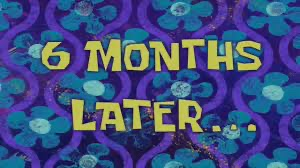

Una vez se extendió el contrato empezamos a trabajar en la identificación del modelo. En aras de establecer el trabajo preliminar para la automatización de este proceso empleamos las funciones del toolbox `systemIdentification` para la ventana de comandos.

## Preprocesamiento

Comenzamos preprocesando los nuevos datos con una serie de funciones de elaboración propia. Primero, verificamos la normalidad de los datos de entrada decidir que métodos de análisis de outliers vamos a incorporar.

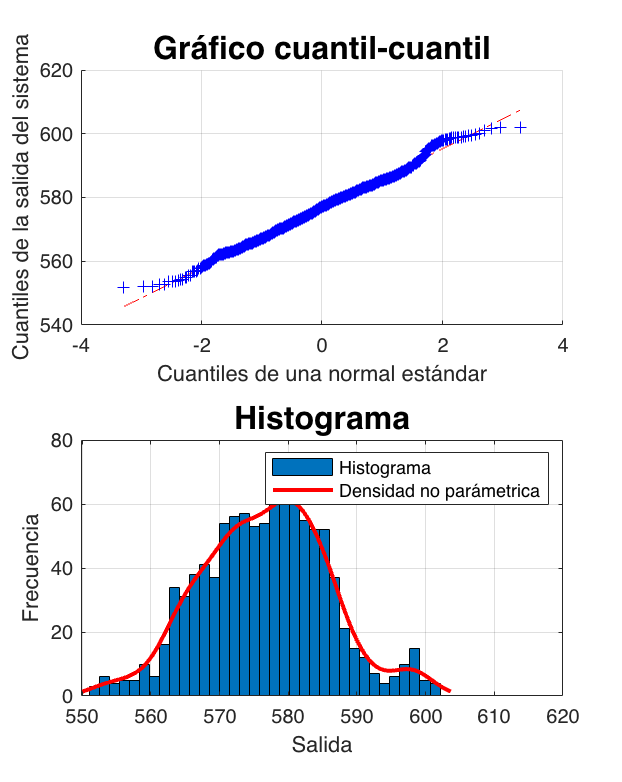

ans = struct with fields:
       ad: {'Anderson-Darling'  'H1'  'H0: Normalidad con enfasis en las colas.'}
       jb: {'Jarque-Bera'  'H0'  'H0: Mean and Variance of normal distriution.'}
     chi2: {'Chi-square goodness-of-fit'  'H1'  'H0: Mean and Variance of normal distriution.'}
    alpha: 0.0500


clear
load DataP1ModExp/data1f.mat
checkGaussian1d(y, 0.05)

Se obtuvieron las mismas conclusiones que para los datos pasados, por lo tanto, se descartan los métodos de amputación de outliers para datos gaussianos. Parece ser que los datos de salida son los mismos puesto que el análisis de datos atípicos llevó a los mismos resultados, es decir, rechazamos la existencia de estos en los datos de salida.

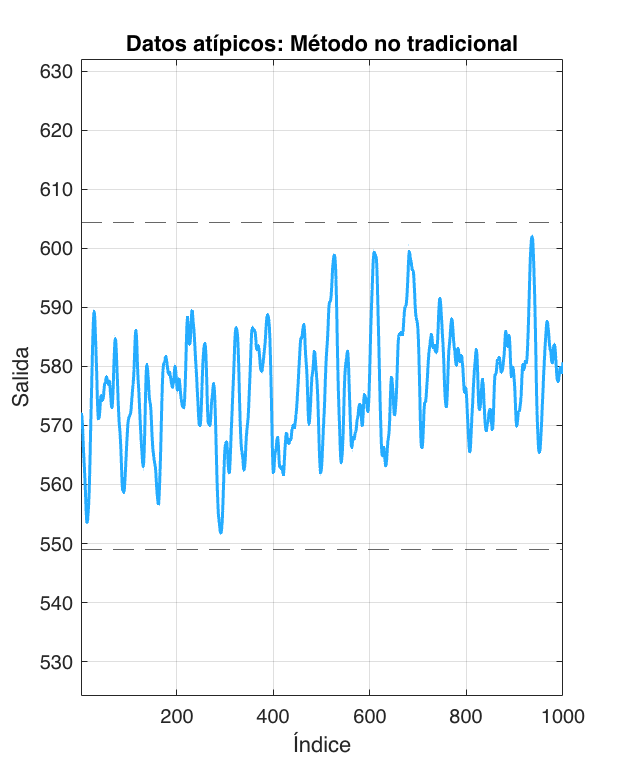


ans =

  1×0 empty double row vector



plot_outliers(y, 'mean')

plot_outliers(y, 'median')


ans =

  1×0 empty double row vector



plot_outliers(y, 'quartile')

Centrando la atención sobre la entrada, se observa un cambio de escala respecto a la anterior en la PRBS, sin embargo, las estimaciones del orden son idénticas al caso anterior. La única diferencia que resalta a la vista es observable a partir de la función de elaboración propia` params_prbs`, la cual indica que las frecuencias empleadas son sucesivas del 1 al 9.

pexcit(iddata(y', u', 1))
params_prbs(u)

Ahora, se procede a emplear la función personal `preprocessing_iddata`, la cual simula el preprocesamiento del *quick start *de la aplicación del toolbox `systemIdentification`. Nótese, la única variable que cambió fue $u$, por lo tanto, empleamos los parámetros estimados por el ingeniero anterior, debido a que como vimos en el informe anterior, eran correctos.

[data, train, test] = preprocessing_iddata(y, u, 1);

## Métodos no paramétricos

### Análisis de autocorrelación

Comenzamos realizando un análisis de autocorrelación, para estimar el retardo. Lo anterior se realiza mediante la función `correlation_impulse`, elaborada por cuenta propia. A partir de la gráfica de respuesta al impulso podemos observar que para un nivel de significancia de $0.001$ el retardo es $d=1$. Por lo tanto, $n_k = 2$, valor que concuerda con la estimación de la función `delayest`.

**Nota:** De ahora en adelante, todos los intervalos de confianza tendrán este nivel de significancia, suponiendo normalidad sobre los errores .

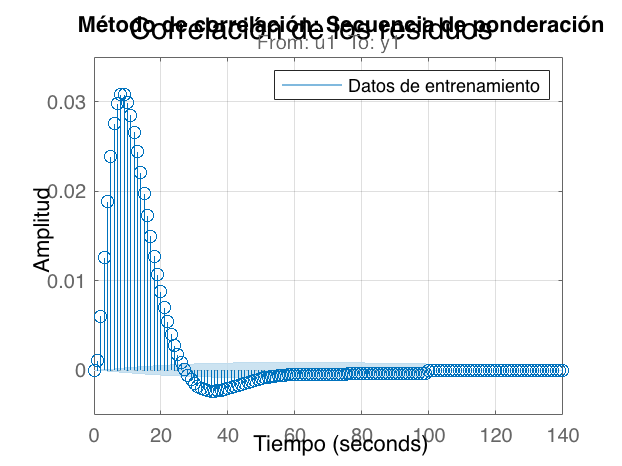

clf
correlation_impulse(train, 100, 0.001)

delayest(train) 

ans = 2

## Modelo espectral

Por su parte, a partir del modelo espectral podemos realizar un diagrama de bode, el cual realizamos con la función personal `spectral_freq_response`. A partir del diagrama observamos que tenemos un comportamiento ideal, puesto que una vez caen las curvas no se evidencia un ruido considerable. Es decir, los datos no requieren ser filtrados, lo cual es valida con el preprocesamiento efectuado.

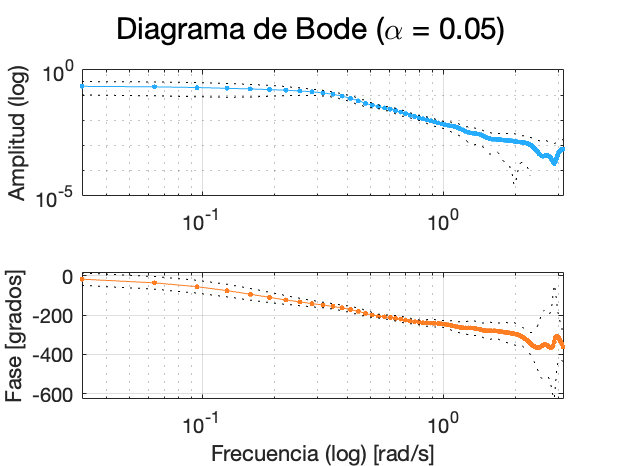

spectral_freq_response(train, 100, 0.001)

## Modelos I-O Polinomiales

Se realizó una exploración extensiva de todos los modelos disponibles en el toolbox: ARX, ARMAX, ARX por VI, OE y BJ. No obstante, solo mostraremos los resultados más importantes, estos solo involucran modelos ARX (tradicional y por variable instrumental). En aras de contribuir a la eventual optimización del procedimiento efectuado en este trabajo, se realizó una función `best_ARX`, la cual explora todos los posibles modelos dentro de un grid establecido por el usuario y escoge las mejores estimaciones considerando tres funciones de costo: mejor ajuste, criterio de información de Akaike y MDL. Nótese que la aplicación del toolbox no tiene incorporado esto para variable instrumental.

% https://la.mathworks.com/help/ident/ref/struc.html
[ARX_bestfit, ARX_AIC, ARX_MDL] = best_ARX(train, test, 1:10, 1:10, 0:2, 'arx');
[IV_bestfit, IV_AIC, IV_MDL] = best_ARX(train, test, 1:10, 1:10, 0:2, 'iv');

Variando $n_a$ y $n_b$ entre 1 y 10, y el retardo $n_k$ de 0 a 2 (considerando la estimación por métodos no paramétricos), la función nos retorna las mejores estimaciones por cada criterio.

## Validación

Para validar los modelos escogidos, comenzamos comparando las estimaciones de los modelos paramétricos con las respuestas asociadas a los modelos no paramétricos, todos  presentaron un comportamiento aceptable, es decir, no hay un criterio de selección a partir de esta comparación y por tanto para ahorrar espacio no se ponen las gráficas.

### Respuesta temporal

Ahora, a partir del ajuste observamos que los métodos por variable instrumental tienen un peor ajuste. aunque preservan la forma de la respuesta temporal. Vale la pena mencionar, que los mismos modelos en la aplicación del toolbox entregaba un mejor ajuste, en efecto, para variable instrumental oscilaba alrededor del 85% y para el ARX 96%, no obstante, la relación de orden entre modelos es la misma. Se destaca que la diferencia en el ajuste entre los modelos por ARX es mínima.

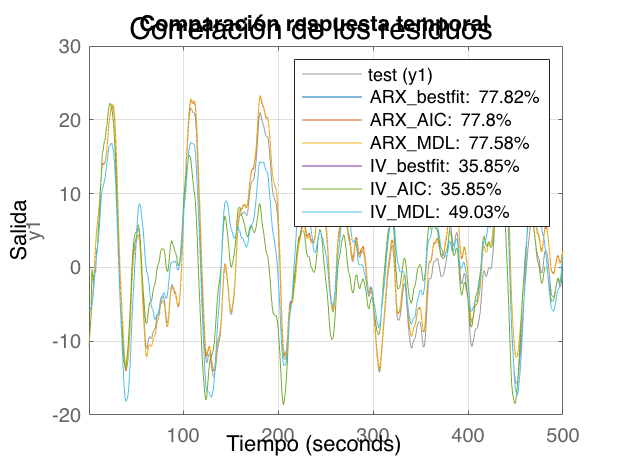

clf
compare(test, ARX_bestfit, ARX_AIC, ARX_MDL, IV_bestfit, IV_AIC, IV_MDL);
grid on
ylabel('Salida'); title('Comparación respuesta temporal'); xlabel('Tiempo')

### Correlación de los residuales

Antes de definir como ganador a la estimación por ARX validamos si los errores no tienen autocorrelación ni correlación cruzada con la entrada, es decir, observamos si el modelo logra blanquear el error. A partir de la figura podemos observar que los modelos estimados por ARX tienen algunos picos significativos, mientras que los estimados por variable instrumental seleccionados por mejor ajuste y AIC no.

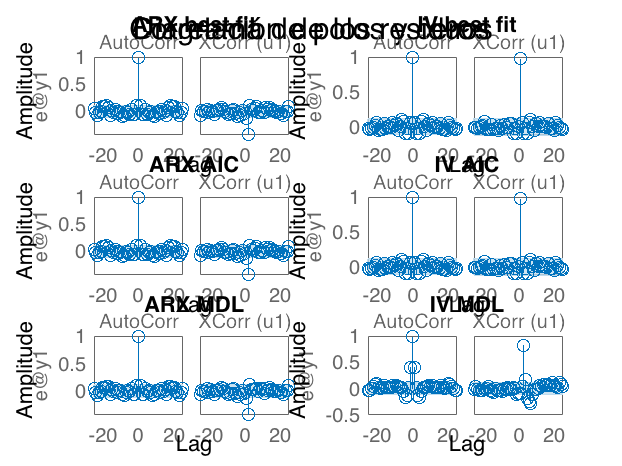

clf
subplot(3, 2, 1)
resid(test, ARX_bestfit)
title('ARX best fit')

subplot(3, 2, 3)
resid(test, ARX_AIC)
title('ARX AIC')

subplot(3, 2, 5)
resid(test, ARX_MDL)
title('ARX MDL')

subplot(3, 2, 2)
resid(test, IV_bestfit)
title('IV best fit')

subplot(3, 2, 4)
resid(test, IV_AIC)
title('IV AIC')

subplot(3, 2, 6)
resid(test, IV_MDL)
title('IV MDL')

sgtitle('Correlación de los residuos')

### Polos y ceros

En aras de observar si hay sustento para reducir el orden de los modelos seleccionados, realizamos un diagrama de polos y ceros con contornos de confianza para cada modelo. A partir de estos se observa que todos los modelos tienen polos y ceros que se pueden cancelar, no obstante, una vez lo hicimos, la correlación de los residuales y el ajuste se deterioró considerablemente, por lo tanto, no fue posible simplificar los modelos. 

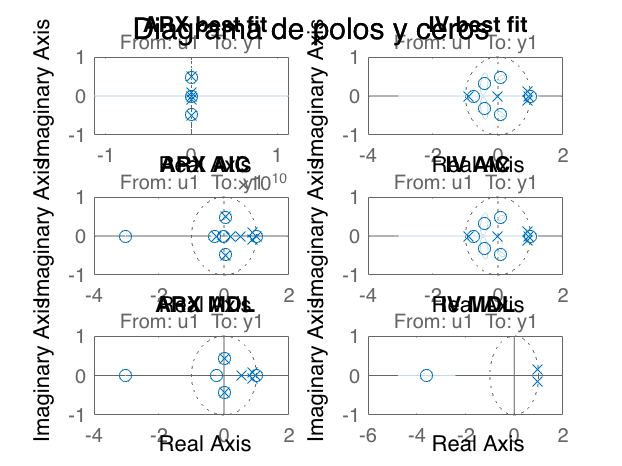

%https://la.mathworks.com/help/ident/ug/refining-linear-parametric-models.html
clf
Alpha = 0.001;
subplot(3, 2, 1)
h = iopzplot(ARX_bestfit); 
showConfidence(h,norminv(1-Alpha))
title('ARX best fit')

subplot(3, 2, 3)
h = iopzplot(ARX_AIC); 
showConfidence(h,norminv(1-Alpha))
title('ARX AIC')

subplot(3, 2, 5)
h = iopzplot(ARX_MDL); 
showConfidence(h,norminv(1-Alpha))
title('ARX MDL')

subplot(3, 2, 2)
h = iopzplot(IV_bestfit); 
showConfidence(h,norminv(1-Alpha))
title('IV best fit')

subplot(3, 2, 4)
h = iopzplot(IV_AIC); 
showConfidence(h,norminv(1-Alpha))
title('IV AIC')

subplot(3, 2, 6)
h = iopzplot(IV_MDL); 
showConfidence(h,norminv(1-Alpha))
title('IV MDL')

sgtitle('Diagrama de polos y ceros')

## Modelo escogido

Claramente no tenemos un modelo dominante, puesto que ARX tiene un ajuste superior con ligeras fallas en la correlación de los residuales mientras que variable instrumental logra blanquear el error. Respecto a los modelos estimados por ARX, escogemos el asociado a la función de costo MDL (ARX 6,6,1), debido a que tiene un ajuste simular a los demás pero un orden menor, es decir, por parsimonia. Nótese, que ninguno de los modelos por ARX consideró un retardo de 2.

Por su parte, entre los modelos estimados por variable instrumental hay un claro ganador: el escogido por mejor ajuste y AIC. Este es un ARX 4, 7, 2, cabe resaltar que aunque este si incorpora el retardo de 2, el orden de la entrada es muy superior al de la salida. Así las cosas escogemos el modelo ARX 6,6,1. 

M_MDL

A continuación se muestra la estimación modelo escogido considerando análisis del error: